Mock test 2 - Fabian-Ionuț Martin, grupa 234/2

1. f:[-2π,2π]->R, f(x) = sinx^2. {x_k:k=0,..9} noduri Cebisev de speta I. t=*π*/5.

    a) Grafic> f, poli. de interpolare Lagrange + Hermite

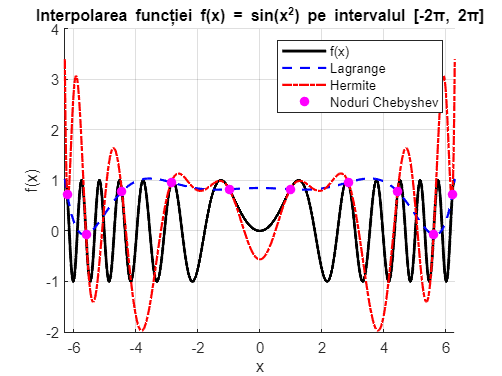

f = @(x) sin(x.^2);

df = matlabFunction(derivataDeOrdinNPlusUnu(f,0));

a = -2*pi;
b = 2*pi;

m = 9;
x_cheb = noduriCebisevDeSpetaI(m, a, b);

y_cheb = f(x_cheb);
dy_cheb = df(x_cheb);

x_plot = noduriEchidistante(a, b, 10000);
y_true = f(x_plot);

% Interpolare Lagrange și Hermite
p_Lagrange = interpolareLagrangeMultiplePoints(x_cheb, y_cheb, x_plot);
p_Hermite = interpolareHermiteMultiplePoints(x_cheb, y_cheb, dy_cheb, x_plot);

% Crearea graficului
figure;
hold on;
plot(x_plot, y_true, 'k-', 'LineWidth', 2);  % funcția originală
plot(x_plot, p_Lagrange, 'b--', 'LineWidth', 1.5);  % polinomul Lagrange
plot(x_plot, p_Hermite, 'r-.', 'LineWidth', 1.5);  % polinomul Hermite
plot(x_cheb, y_cheb, 'mo', 'MarkerFaceColor', 'm');  % nodurile Chebyshev
legend('f(x)', 'Lagrange', 'Hermite', 'Noduri Chebyshev');
title('Interpolarea funcției f(x) = sin(x^2) pe intervalul [-2\pi, 2\pi]');
xlabel('x');
ylabel('f(x)');
grid on;
hold off;

    b) Aproximați f(t) cu ajutorul polinoamelor de la a).

t = pi / 5;

% Folosind punctul a), putem cauta care punct este mai aproape de t din
% x_plot
t_index = find(abs(x_plot - t) < 1e-3)  

t_index =         5500        5501


approx_Lagrange = p_Lagrange(t_index)

approx_Lagrange =     0.8353    0.8352


approx_Hermite = p_Hermite(t_index);

true_value = f(t);

fprintf('Valoarea exactă la t = pi/5 este: %f\n', true_value);

Valoarea exactă la t = pi/5 este: 0.384609


fprintf('Aproximația Lagrange la t = pi/5 este: %f\n', approx_Lagrange);

Aproximația Lagrange la t = pi/5 este: 0.835292
Aproximația Lagrange la t = pi/5 este: 0.835249


fprintf('Aproximația Hermite la t = pi/5 este: %f\n', approx_Hermite);

Aproximația Hermite la t = pi/5 este: 0.244289
Aproximația Hermite la t = pi/5 este: 0.246735



% Sau folosind direct rutinele pentru interpolarea Lagrange/Hermite intr-un
% punct dat
approx_Lagrange = interpolareLagrange(x_cheb, y_cheb, t);
approx_Hermite = interpolareHermite(x_cheb, y_cheb, dy_cheb, t);

fprintf('Valoarea exactă la t = pi/5 este: %f\n', true_value);

Valoarea exactă la t = pi/5 este: 0.384609


fprintf('Aproximația Lagrange la t = pi/5 este: %f\n', approx_Lagrange);

Aproximația Lagrange la t = pi/5 este: 0.835273


fprintf('Aproximația Hermite la t = pi/5 este: %f\n', approx_Hermite);

Aproximația Hermite la t = pi/5 este: 0.245390


    c) pentru fiecare interpolant, evaluati eroarea teoretic (cu ajutorul expresiei restului) si practic 

max_error_Lagrange = max(abs(y_true - p_Lagrange));
max_error_Hermite = max(abs(y_true - p_Hermite));
% Afișarea erorilor maxime
fprintf('Eroare maximă Lagrange la t = pi/5: %.10f\n',max_error_Lagrange);

Eroare maximă Lagrange la t = pi/5: 2.0247668938


fprintf('Eroare maximă Hermite la t = pi/5:  %.10f\n', max_error_Hermite);

Eroare maximă Hermite la t = pi/5:  3.8131283618



derivative = derivataDeOrdinNPlusUnu(f, m) % Calculează derivata de ordin n+1

$$derivative = 30240\,\cos\left(x^{2}\right)-403200\,x^{4}\,\cos\left(x^{2}\right)+23040\,x^{8}\,\cos\left(x^{2}\right)-302400\,x^{2}\,\sin\left(x^{2}\right)+161280\,x^{6}\,\sin\left(x^{2}\right)-1024\,x^{10}\,\sin\left(x^{2}\right)$$

derivative_func = matlabFunction(derivative) % Transformă derivata simbolică în funcție numerică

derivative_func = function_handle with value:
    @(x)cos(x.^2).*3.024e+4-x.^4.*cos(x.^2).*4.032e+5+x.^8.*cos(x.^2).*2.304e+4-x.^2.*sin(x.^2).*3.024e+5+x.^6.*sin(x.^2).*1.6128e+5-x.^10.*sin(x.^2).*1.024e+3



% Utilizarea funcțiilor de calcul al restului
% Aici nu inteleg de ce va fi valoarea asa mare a restului, poate ceva am
% gresit pentru calculeazaRestulLagrange
rest_Lagrange = calculeazaRestulLagrange(t, x_cheb, derivative_func);
rest_Hermite = calculeazaRestulHermite(t, x_cheb, derivative_func);

% Afișarea erorilor teoretice
fprintf('Eroare teoretică Lagrange la t = pi/5: %.10f\n',rest_Lagrange);

Eroare teoretică Lagrange la t = pi/5: 181.2458338133


fprintf('Eroare teoretică Hermite la t = pi/5:  %.10f\n', rest_Hermite);

Eroare teoretică Hermite la t = pi/5:  -0.0000142926



% Calculul erorii practice
practical_error_Lagrange = abs(true_value - approx_Lagrange);
practical_error_Hermite = abs(true_value - approx_Hermite);

fprintf('Eroare practică Lagrange la t = pi/5: %f\n', practical_error_Lagrange);

Eroare practică Lagrange la t = pi/5: 0.450664


fprintf('Eroare practică Hermite la t = pi/5: %f\n', practical_error_Hermite);

Eroare practică Hermite la t = pi/5: 0.139219


2. f(x) = x^2sinx pe [-2π,2π]

    a) splie deBoor cu noduri echidistante, respectiv Cebîșev de speța a II-a, n=12

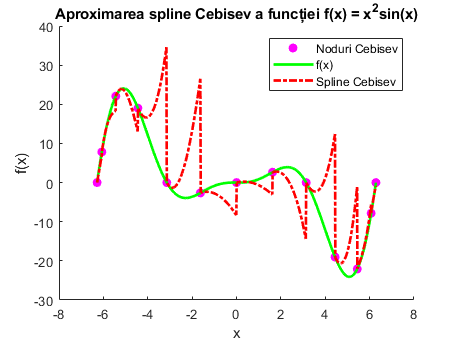

f = @(x) x.^2.*sin(x);

m = 12;
x_cheb2 = noduriCebisevDeSpetaII(m, a, b);
y_cheb2 = f(x_cheb2);

x_echi = noduriEchidistante(a,b,m);
y_echi = f(x_echi);

t_cheb2 = noduriCebisevDeSpetaII(999, a, b)';
yg_cheb2 = f(t_cheb2);
t = noduriEchidistante(a, b, 1000)';
yg=f(t);

% deBoor Cebisev
[a1,b1,c1,d1]=CubicSpline(x_cheb2,y_cheb2,[0,0],3);
s1=evaluate_spline(x_cheb2,a1,b1,c1,d1,t_cheb2);
% deBoor echidistante
[a2,b2,c2,d2]=CubicSpline(x_echi,y_echi,[0,0],3);
s2=evaluate_spline(x_echi,a2,b2,c2,d2,t);

figure;
hold on;
plot(x_cheb2, y_cheb2, 'mo', 'MarkerFaceColor', 'm'); % Nodurile Cebisev
plot(t_cheb2, yg_cheb2, 'g-', 'LineWidth', 2);  % Funcția originală
plot(t_cheb2, s1, 'r-.', 'LineWidth', 2); % Aproximarea spline Cebisev
legend('Noduri Cebisev', 'f(x)', 'Spline Cebisev');
title('Aproximarea spline Cebisev a funcției f(x) = x^2sin(x)');
xlabel('x');
ylabel('f(x)');
hold off;

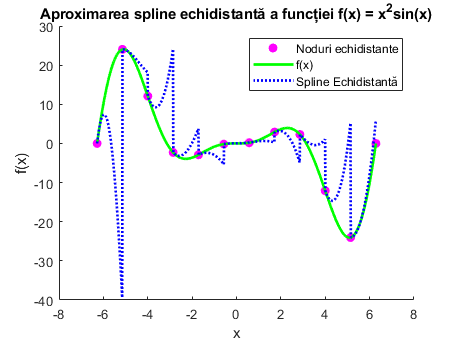


figure;
hold on;
plot(x_echi, y_echi, 'mo', 'MarkerFaceColor', 'm'); % Nodurile echidistante
plot(t, yg, 'g-', 'LineWidth', 2);  % Funcția originală
plot(t, s2, 'b:', 'LineWidth', 2);  % Aproximarea spline echidistantă
legend('Noduri echidistante', 'f(x)', 'Spline Echidistantă');
title('Aproximarea spline echidistantă a funcției f(x) = x^2sin(x)');
xlabel('x');
ylabel('f(x)');
hold off;

b) metoda celor mai mici pătrate și noduri echidistante, n=11

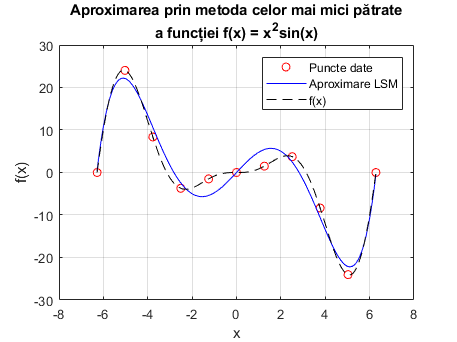

m = 11;

x_echi = noduriEchidistante(a,b,m);
y_echi = f(x_echi);
phi = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4; x.^5; x.^6];
xAprox = noduriEchidistante(a,b,1000);
yAprox = MetodaCelorMaiMiciPatrate(x_echi, y_echi, phi, xAprox);

figure;
plot(x_echi, y_echi, 'ro', 'DisplayName', 'Puncte date'); 
hold on;
plot(xAprox, yAprox, 'b-', 'DisplayName', 'Aproximare LSM');
plot(xAprox, f(xAprox), 'k--', 'DisplayName', 'f(x)');
legend show;
title({'Aproximarea prin metoda celor mai mici pătrate', 'a funcției f(x) = x^2sin(x)'});
xlabel('x');
ylabel('f(x)');
grid on;